Завантаження і первісна обробка файлу

[file, path] = uigetfile({'*.jpg;*.png','Image Files'}, 'Вибери зображення');
if isequal(file,0)
    disp('Користувач скасував вибір');
    return;
end
img = imread(fullfile(path, file));

% Переведення в сіре зображення, якщо кольорове
if size(img, 3) == 3
    grayImg = rgb2gray(img);
else
    grayImg = img;
end

Покращення контрасту, бінаризація (адаптивна)

grayImg = imadjust(grayImg); 
bw = imbinarize(grayImg,'adaptive','ForegroundPolarity','dark','Sensitivity', 0.525)

bw = 1280×960 logical array
   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   1   0   0   1   1   0   0   0   0   1   1   1   0
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   1   1   1   1   1   1   1   1   0
   1   1   1   1   1   1   1   1   0   1   1   1   1   1   1   1   1   1   1   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1

Показ проміжних результатів

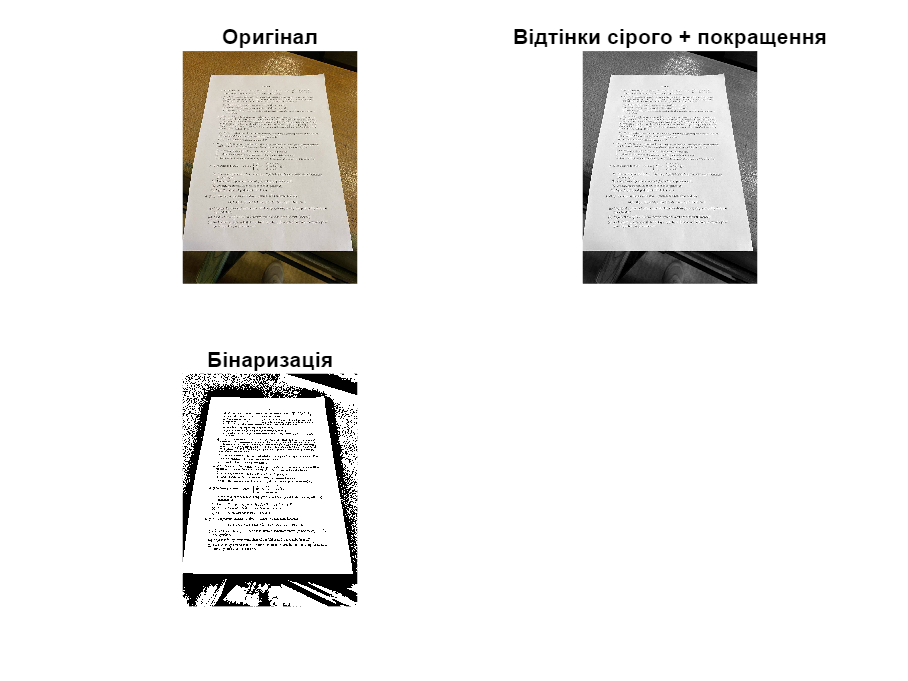

figure;
subplot(2,2,1); imshow(img); title('Оригінал');
subplot(2,2,2); imshow(grayImg); title('Відтінки сірого + покращення');
subplot(2,2,3); imshow(bw); title('Бінаризація');

Якщо результат бінаризації задовільний, переходимо до трансформації геометричної форми зображення

figure; imshow(bw); title('Вибери 4 кути документа (за годинниковою стрілкою, починаючи з верхнього лівого)');
[x, y] = ginput(4); 
close;

srcPoints = [x y];
w = norm(srcPoints(1,:) - srcPoints(2,:));
h = norm(srcPoints(1,:) - srcPoints(4,:));
aspectRatio = h / w;

outputWidth = 800;
outputHeight = round(outputWidth * aspectRatio);
targetPoints = [0 0; outputWidth 0; outputWidth outputHeight; 0 outputHeight];

tform = fitgeotrans(srcPoints, targetPoints, 'projective');
aligned = imwarp(bw, tform, 'OutputView', imref2d([outputHeight outputWidth]));

Виведення і збереження результатів

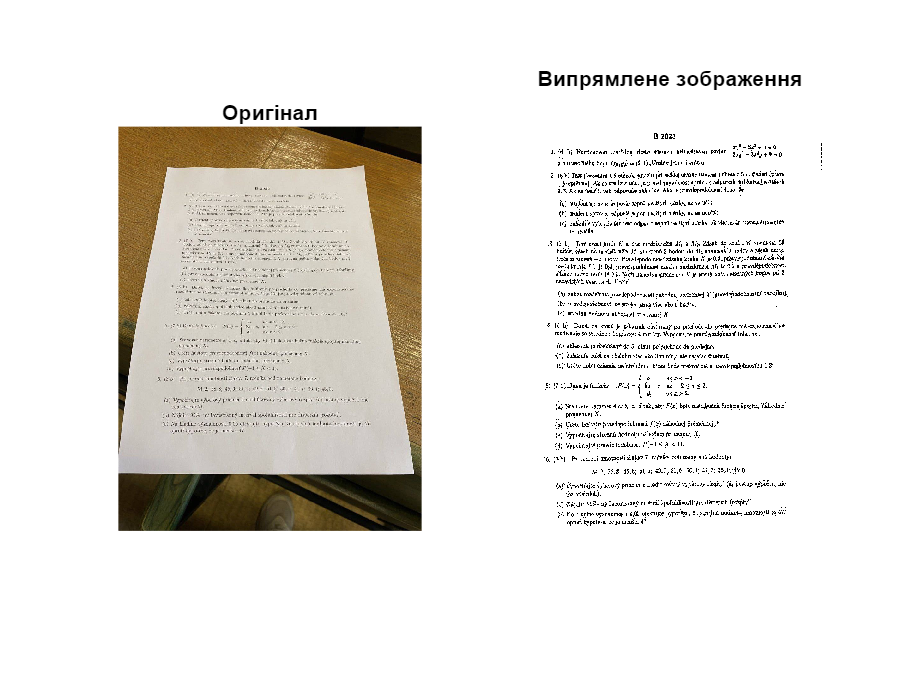

figure;
subplot(1,2,1); imshow(img); title('Оригінал');
subplot(1,2,2); imshow(aligned); title('Випрямлене зображення');


imwrite(aligned, fullfile(path, ['антижмих_' file]));